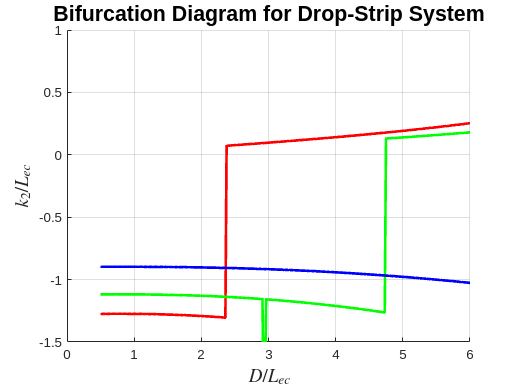

% Parameters
EI = 1;               % Elastic stiffness
rgS = 1;              % Gravitational constant
gamma = 1;            % Surface tension
w = 1;                % Width of the strip
Lec = sqrt(EI / (rgS * w)); % Elastic-capillary length
L_values = [14, 16, 20] * Lec; % Strip lengths
D_Lec_vals = linspace(0.5, 6, 300); % Normalized wet region extent
bifurcation_data = cell(length(L_values), 1); % Store results

% Energy minimization loop
for j = 1:length(L_values)
    L = L_values(j); % Current strip length
    k2_vals = zeros(length(D_Lec_vals), 1);
    b_vals = zeros(length(D_Lec_vals), 1);
    stability = zeros(length(D_Lec_vals), 1); % Stable (1) or unstable (0)
    
    for i = 1:length(D_Lec_vals)
        D = D_Lec_vals(i) * Lec; % Actual wet region extent
        
        % Objective function: Total energy
        energy_function = @(x) compute_energy(x, D, L, EI, rgS, gamma, w);
        
        % Adjusted initial guess for [b, k2]
        x0 = [pi/6, -0.1]; % Starting near expected values
        
        % Minimize energy
        options = optimoptions('fminunc', 'Display', 'off', 'Algorithm', 'quasi-newton');
        [x_sol, fval, exitflag] = fminunc(energy_function, x0, options);
        
        % Store results
        b_vals(i) = x_sol(1);
        k2_vals(i) = x_sol(2);
        
        % Stability analysis (second derivative of energy)
        hessian = compute_hessian(x_sol, D, L, EI, rgS, gamma, w);
        stability(i) = all(eig(hessian) > 0); % Stable if positive definite
    end
    
    % Store data for current length
    bifurcation_data{j} = struct('D_Lec', D_Lec_vals, 'k2', k2_vals, ...
                                 'b', b_vals, 'stability', stability);
end

% Plot bifurcation diagram
figure;
hold on;
colors = ['r', 'g', 'b']; % Colors for different lengths

for j = 1:length(L_values)
    data = bifurcation_data{j};
    stable_idx = data.stability == 1;
    unstable_idx = data.stability == 0;
    
    % Plot stable and unstable branches
    plot(data.D_Lec(stable_idx), data.k2(stable_idx), '-', 'LineWidth', 2, ...
         'Color', colors(j), 'DisplayName', sprintf('Stable (L/Lec = %.1f)', L_values(j) / Lec));
    plot(data.D_Lec(unstable_idx), data.k2(unstable_idx), '--', 'LineWidth', 2, ...
         'Color', colors(j), 'DisplayName', sprintf('Unstable (L/Lec = %.1f)', L_values(j) / Lec));
end

% Add labels and legend
xlabel('$D/L_{ec}$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$k_2/L_{ec}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Bifurcation Diagram for Drop-Strip System', 'FontSize', 16);
xlim([0,6]);
ylim([-1.5,1]);
%legend show;
grid on;
hold off;


% Total energy computation function
function E = compute_energy(x, D, L, EI, rgS, gamma, w)
    b = x(1); % Deflection angle
    k2 = x(2); % Curvature in the dry region
    
    % Elastic energy (wetted region)
    k1 = b / D; % Curvature
    E_el1 = EI * k1^2 * D;
    
    % Gravitational energy (wetted region)
    E_g1 = 2 * rgS * (k1 * D - sin(k1 * D)) / k1^2;
    
    % Elastic energy (dry region)
    E_el2 = EI * (L - D) * k2^2 / 3;
    
    % Gravitational energy (dry region)
    E_g2 = 2 * rgS * (L - D) * (1/k1 * (1 - cos(b)) + 1/k2 * (cos(b) - cos(b + 0.5 * k2 * (L - D))));
    
    % Surface energy
    R = D * (sin(b) / b); % Radius
    E_s = 2 * gamma * R * w;
    
    % Total energy
    E = E_el1 + E_g1 + E_el2 + E_g2 + E_s;
end

% Hessian computation for stability analysis
function H = compute_hessian(x, D, L, EI, rgS, gamma, w)
    % Numerical second derivatives
    eps = 1e-5; % Small perturbation
    H = zeros(2, 2);
    for i = 1:2
        for j = 1:2
            x_ij = x;
            x_ij(i) = x_ij(i) + eps;
            x_ij(j) = x_ij(j) + eps;
            E_ij = compute_energy(x_ij, D, L, EI, rgS, gamma, w);
            
            x_i = x; x_i(i) = x_i(i) + eps;
            x_j = x; x_j(j) = x_j(j) + eps;
            E_i = compute_energy(x_i, D, L, EI, rgS, gamma, w);
            E_j = compute_energy(x_j, D, L, EI, rgS, gamma, w);
            
            E = compute_energy(x, D, L, EI, rgS, gamma, w);
            
            H(i, j) = (E_ij - E_i - E_j + E) / eps^2;
        end
    end
end
